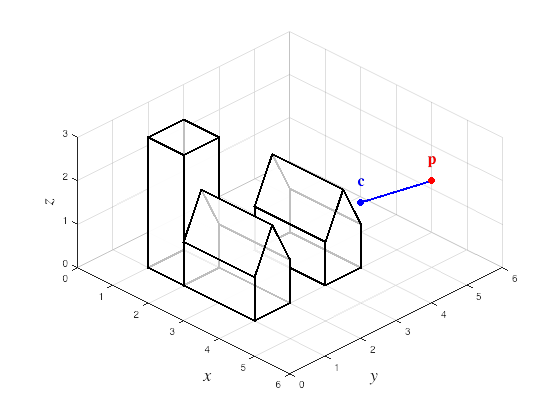

% Define house object
Vhouse = [-0.5, 0.5, 0.5, -0.5, -0.5, 0.5, 0.5, -0.5, 0, 0 ;
     -1,  -1,   1,    1,   -1,  -1,   1,    1,  -1, 1 ;
      0,   0,   0,    0,    1,   1,   1,    1,   2, 2 ;
      1,   1,   1,    1,    1,   1,   1,    1,   1, 1];

Fhouse = [4, 3, 2, 1, 1 ;
          1, 2, 6, 9, 5 ;
          2, 3, 7, 6, 6 ;
          3, 4, 8, 10, 7 ;
          1, 5, 8, 4, 4 ;
          6, 7, 10, 9, 9 ;
          5, 9, 10, 8, 8 ];

% Define cube object
Vcube = [-1,  1,  1, -1, -1,  1, 1, -1 ;
         -1, -1,  1,  1, -1, -1, 1,  1 ;
         -1, -1, -1, -1,  1,  1, 1,  1 ;
          1,  1,  1,  1,  1,  1, 1,  1 ];

Fcube = [1, 4, 3, 2, 2 ;
         1, 2, 6, 5, 5 ; 
         2, 3, 7, 6, 6 ;
         3, 4, 8, 7, 7 ;
         4, 1, 5, 8, 8 ;
         5, 6, 7, 8, 8 ];

% Define transformation parmeters
theta = pi / 2;
c1 = [3, 3.5, 0];
c2 = [3, 1.5, 0];
c3 = [1.5, 1.5, 1.5];
s = [0.5, 0.5, 1.5];

% Define transformation functions
T = @(t) [1, 0, 0, t(1) ; 
          0, 1, 0, t(2) ; 
          0, 0, 1, t(3) ; 
          0, 0, 0, 1];

S = @(s) [s(1), 0,    0,    0 ;  
          0,    s(2), 0,    0 ; 
          0,    0,    s(3), 0 ; 
          0,    0,    0,    1];

Rz = @(theta) [ cos(theta), sin(theta), 0, 0 ;
               -sin(theta), cos(theta), 0, 0 ;
               0,           0,          1, 0 ;
               0,           0,          0, 1];

% Add first house object
Vobj = T(c1) * Rz(theta) * Vhouse;
Fobj = Fhouse;

Vworld = Vobj;
F = Fobj;

% Add second house object
Vobj = T(c2) * Rz(theta) * Vhouse;
Fobj = Fhouse + size(Vworld, 2); % add number of vertices in world space to face array

Vworld = [Vworld, Vobj];
F = [F ; Fobj];

% Add tower object
Vobj = T(c3) * S(s) * Vcube;
Fobj = Fcube + size(Vworld, 2);

Vworld = [Vworld, Vobj];
F = [F ; Fobj];

% Define camera position and centre of view
p = [5, 5, 2];
c = [4, 4, 1.5];
k = [0, 0, 1];
v = c - p;

% Plot world space
patch('Vertices', Vworld(1:3,:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=2)
hold on
plot3(p(1), p(2), p(3), 'ro', MarkerFaceColor='r')
plot3(c(1), c(2), c(3), 'bo', MarkerFaceColor='b')
quiver3(p(1), p(2), p(3), v(1), v(2), v(3), 0, 'b', LineWidth=2)
hold off
text(p(1), p(2), p(3)+0.5, '$\mathbf{p}$', FontSize=16, Interpreter='latex', HorizontalAlignment='center', Color='r')
text(c(1), c(2), c(3)+0.5, '$\mathbf{c}$', FontSize=16, Interpreter='latex', HorizontalAlignment='center', Color='b')

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
view(45, 30)
axis equal
axis([0, 6, 0, 6, 0, 3])
grid on

figure()

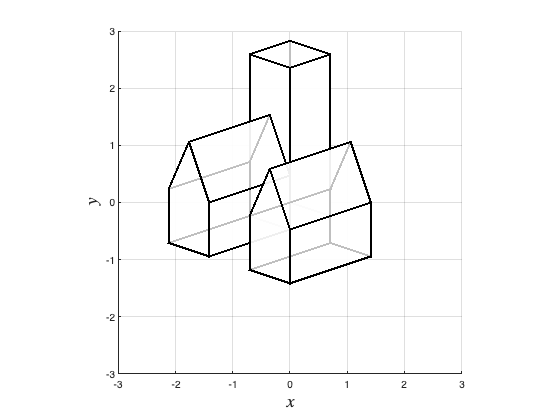

% Define camera position and centre of view
% p = [6, 5, 2];
% c = [5, 4, 1.5];
% k = [0, 0, 1];

% Calculate basis vectors
w = (p - c) / norm(p - c);
u = cross(k, w) / norm(cross(k, w));
v = cross(w, u);

% Calculate change of basis matrix
A = [ u, -dot(p, u) ; 
      v, -dot(p, v) ;
      w, -dot(p, w) ;
      0, 0, 0, 1 ];

% Align world space to the camera
Vcamera = A * Vworld;

% Plot camera space
patch('Vertices', Vcamera(1:3,:)', 'Faces', F, 'FaceColor', 'white', 'FaceAlpha', 0.75, 'LineWidth', 2)
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
view(0, 90)
axis equal
axis([-3, 3, -3, 3, -8, 0])
grid on